This code Will run the autoExperimentAnalysis with all the logs available in batch process....

**remember to uncheck the singleTrial Analaysis in the AutoExperimentAnalysis file.**

**This file will create the TrialData.mat. you should save the variable manuallly **in the last section.

%rememebr the averageCAT being used here skipped the detailed blocke struct in each trial.


clear ;
clc;


% Get the current working directory
cwd = pwd;

% Set the parent directory
allDataFolderPath = 'logs\firstSeries\';
[dirNames,dirPaths] = list_subfolders(allDataFolderPath)

dirNames = 1×12 cell array
    {'Alireza Alialsgari_21-11-2022_18-58-44'}    {'Alireza Aliasgari_11-01-2023_08-49-21'}    {'Alireza Ghaderi_07-02-2023_10-28-46'}    {'Alireza Ghaderi_07-11-2022_10-29-26'}    {'Alireza Ghaderi_07-11-2022_16-50-23'}    {'Alireza Ghaderi_08-01-2023_07-35-20'}    {'Alireza Ghaderi_10-02-2023_10-16-42'}    {'Alireza Ghaderi_12-02-2023_04-20-58'}    {'Alireza Ghaderi_12-02-2023_11-07-17'}    {'Alireza Ghaderi_13-02-2023_04-48-50'}    {'Alireza Ghaderi_14-02-2023_04-18-01'}    {'Alireza Ghaderi_17-01-2023_07-19-41'}


dirPaths = 1×12 cell array
    {'logs\firstSeries\Alireza Alialsgari_21-11-2022_18-58-44'}    {'logs\firstSeries\Alireza Aliasgari_11-01-2023_08-49-21'}    {'logs\firstSeries\Alireza Ghaderi_07-02-2023_10-28-46'}    {'logs\firstSeries\Alireza Ghaderi_07-11-2022_10-29-26'}    {'logs\firstSeries\Alireza Ghaderi_07-11-2022_16-50-23'}    {'logs\firstSeries\Alireza Ghaderi_08-01-2023_07-35-20'}    {'logs\firstSeries\Alireza Ghaderi_10-02-2023_10-16-42'}    {'logs\firstSeries\Alireza Ghaderi_12-02-2023_04-20-58'}    {'logs\firstSeries\Alireza Ghaderi_12-02-2023_11-07-17'}    {'logs\firstSeries\Alireza Ghaderi_13-02-2023_04-48-50'}    {'logs\firstSeries\Alireza Ghaderi_14-02-2023_04-18-01'}    {'logs\firstSeries\Alireza Ghaderi_17-01-2023_07-19-41'}


Test Dir
logs\firstSeries\Alireza Alialsgari_21-11-2022_18-58-44
Pilot Info
           name: 'Alireza Alialsgari'
         rating: 'Student'
       beginPVT: 477
         endPVT: 481
     hoursAwake: 6
     selfRating: 7
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [25026×22 table]
    description: {''}
           time: "21-Nov-2022 18:58:44"
        caffein: 'Low'

Before Test CAT
After Test CAT


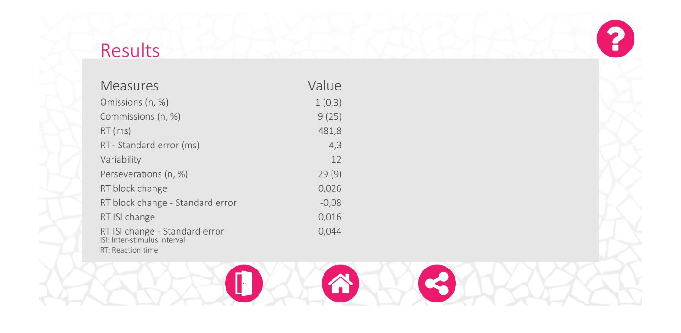

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris      aileron       elevator     throttle       rudder        roll         pitch        hdev         vdev       dmeNM        ias       altitude       vvi       heading       rpm      latitude    longitude
    __    ________________    _____    _____    ______    ______    ___________    __________    _________    __________    _________    _______

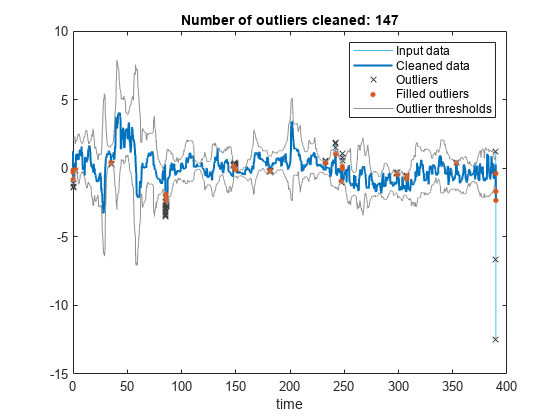

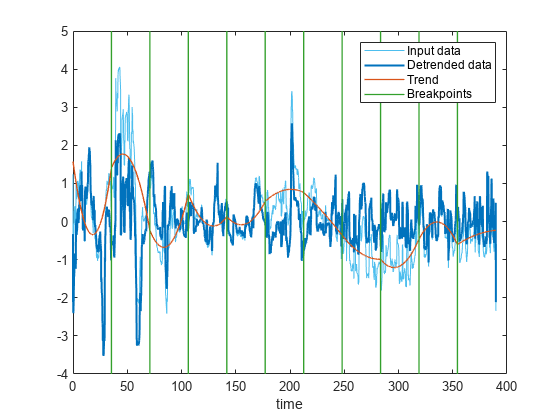

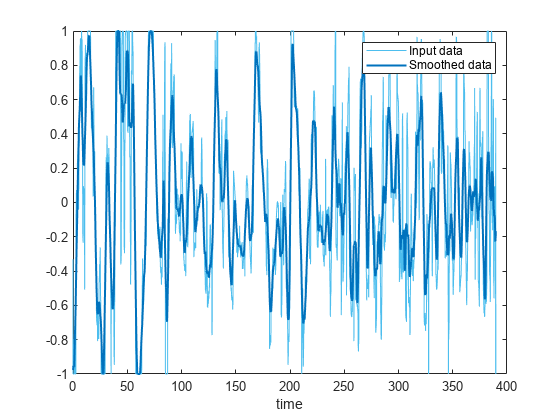

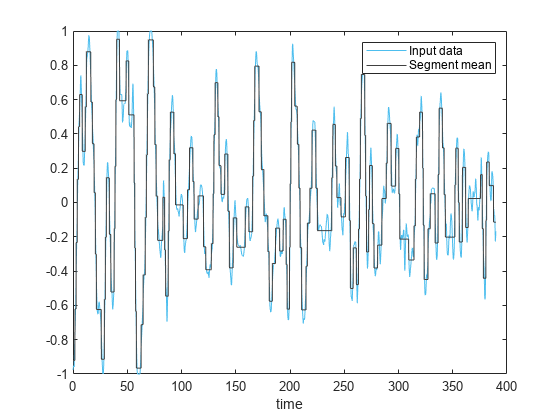

irisResult = struct with fields:
         meanFixation: 2.457112526539278
          varFixation: 3.663490754350620
    numFixationPerMin: 24.168305823997265


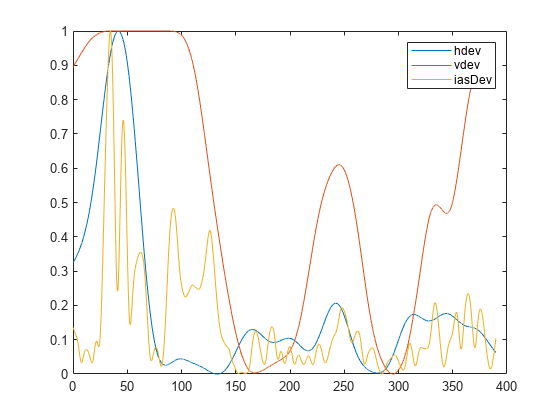

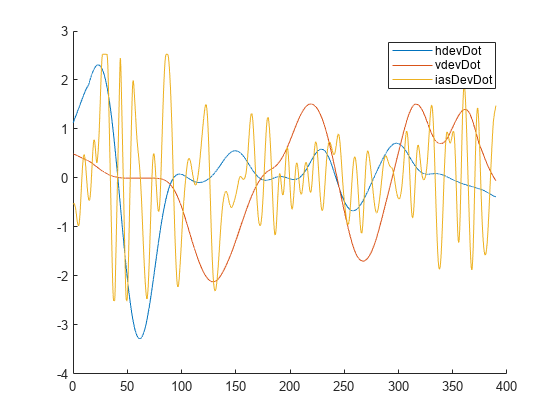

exceedanceResult = struct with fields:
    meanExceedance: 0.565115654588791


exceedanceResult = struct with fields:
    meanExceedance: 0.565115654588791
     varExceedance: 0.086508712916759


exceedanceResult = struct with fields:
            meanExceedance: 0.565115654588791
             varExceedance: 0.086508712916759
    detrendedVarExceedance: 0.063341097568622


Test Dir
logs\firstSeries\Alireza Aliasgari_11-01-2023_08-49-21
Pilot Info
           name: 'Alireza Aliasgari'
         rating: 'Student'
       beginPVT: 482
         endPVT: 509
     hoursAwake: 6
     selfRating: 6
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [36308×22 table]
    description: {''}
           time: "11-Jan-2023 08:49:21"
        caffein: 'None'

Before Test CAT
After Test CAT


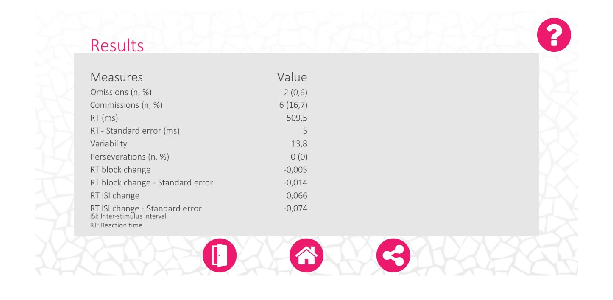

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron       elevator      throttle       rudder         roll        pitch      hdev      vdev        dmeNM        ias      altitude      vvi       heading       rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    __________    ___________    _________    ___________    _________    ________

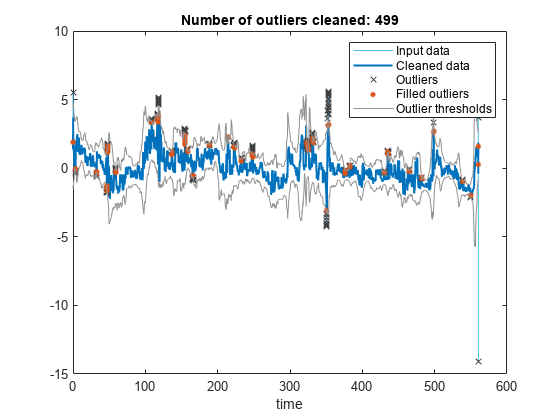

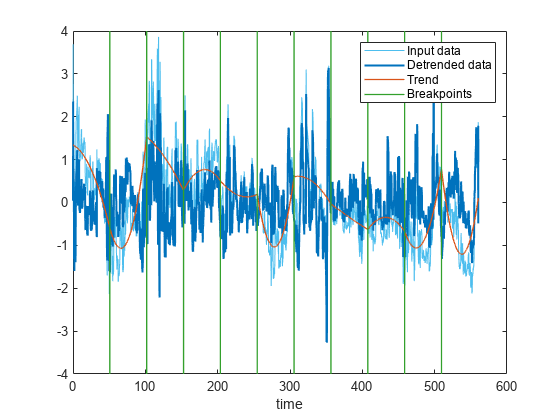

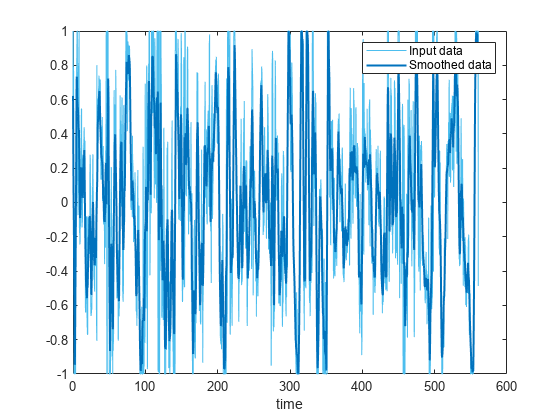

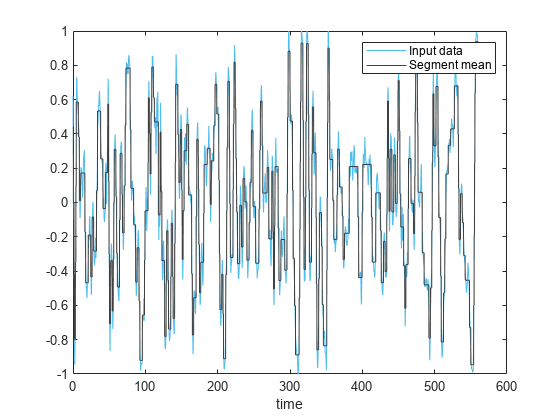

irisResult = struct with fields:
         meanFixation: 2.113434727503169
          varFixation: 2.710997784421286
    numFixationPerMin: 28.160133246088872


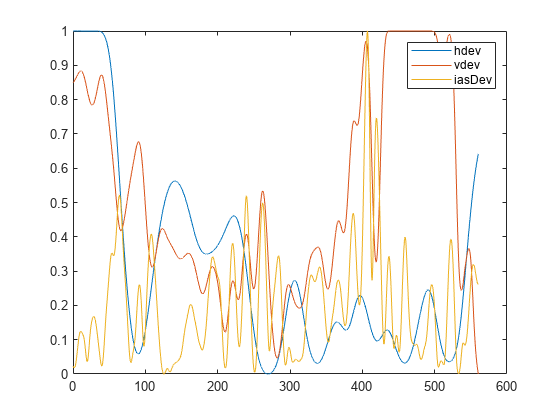

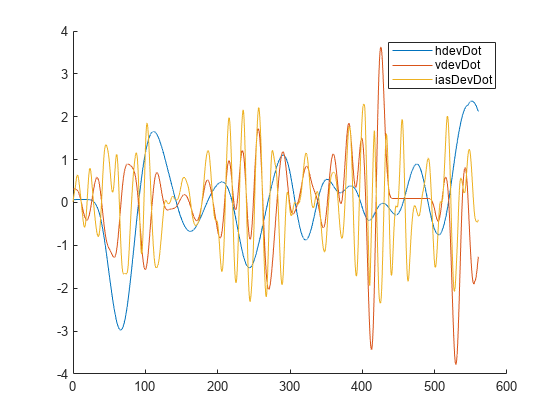

exceedanceResult = struct with fields:
    meanExceedance: 0.622327772261425


exceedanceResult = struct with fields:
    meanExceedance: 0.622327772261425
     varExceedance: 0.051632740312854


exceedanceResult = struct with fields:
            meanExceedance: 0.622327772261425
             varExceedance: 0.051632740312854
    detrendedVarExceedance: 0.048205350016586


Test Dir
logs\firstSeries\Alireza Ghaderi_07-02-2023_10-28-46
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 389
         endPVT: 371
     hoursAwake: 7
     selfRating: 3
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [25295×22 table]
    description: {'Many Distruptions'}
           time: "07-Feb-2023 10:28:46"
        caffein: 'None'

Before Test CAT
After Test CAT


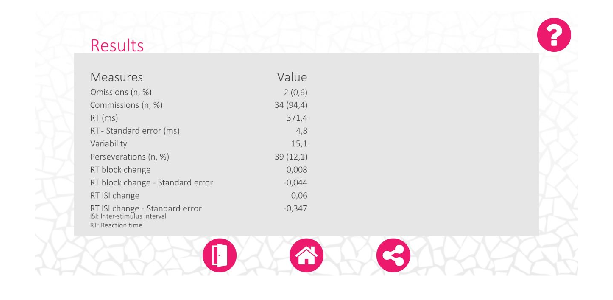

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron       elevator      throttle      rudder        roll        pitch         hdev         vdev       dmeNM        ias       altitude       vvi       heading       rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    __________    ___________    _________    _________    _________    ________

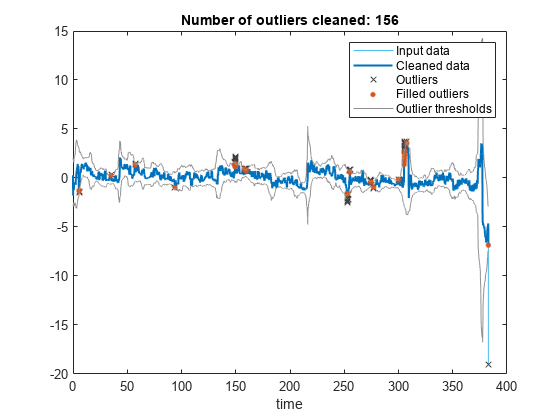

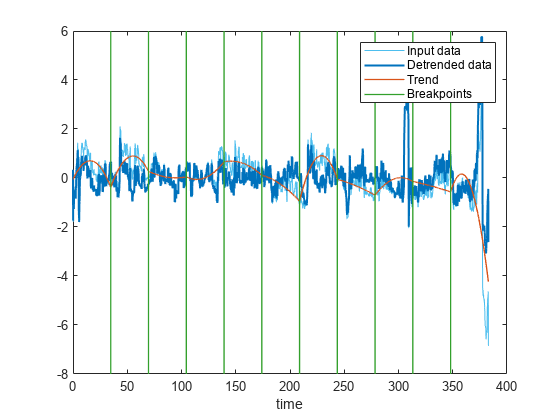

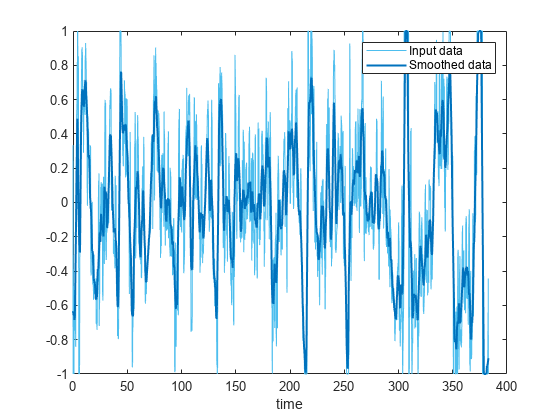

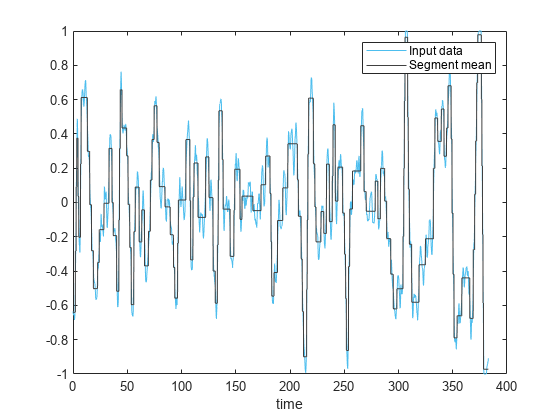

irisResult = struct with fields:
         meanFixation: 2.612731481481481
          varFixation: 3.932758298799965
    numFixationPerMin: 22.568567696996080


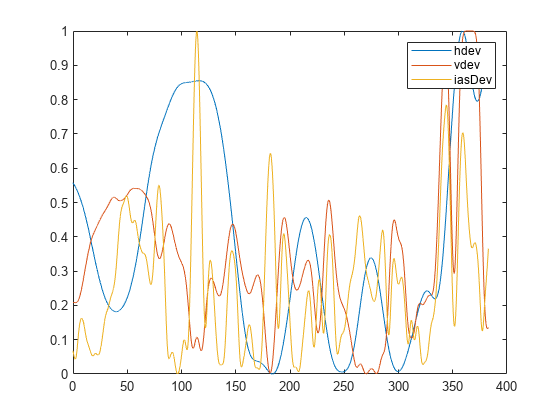

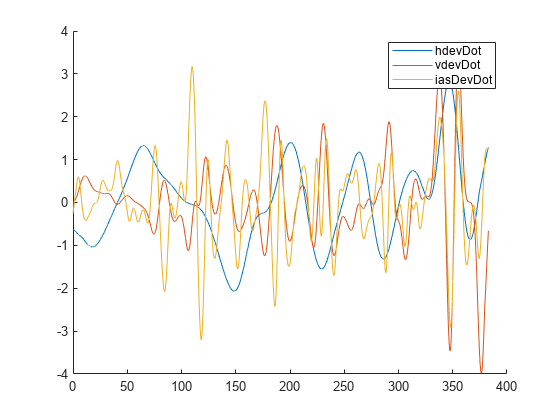

exceedanceResult = struct with fields:
    meanExceedance: 0.518309513694699


exceedanceResult = struct with fields:
    meanExceedance: 0.518309513694699
     varExceedance: 0.046024381660347


exceedanceResult = struct with fields:
            meanExceedance: 0.518309513694699
             varExceedance: 0.046024381660347
    detrendedVarExceedance: 0.046534049857514


Test Dir
logs\firstSeries\Alireza Ghaderi_07-11-2022_10-29-26
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 376
         endPVT: 373
     hoursAwake: 7
     selfRating: 6
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [28490×22 table]
    description: {''}
           time: "07-Nov-2022 10:29:26"
        caffein: 'None'

Before Test CAT
After Test CAT


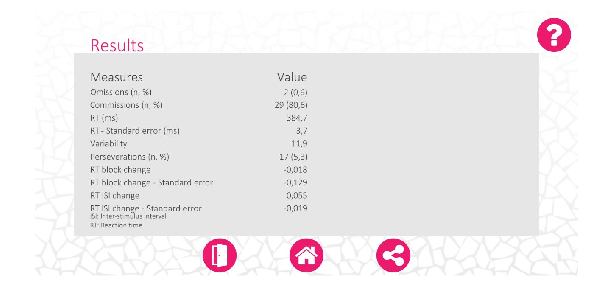

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron       elevator     throttle      rudder       roll        pitch        hdev         vdev        dmeNM        ias       altitude       vvi       heading       rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    __________    __________    _________    ________    _________    ________

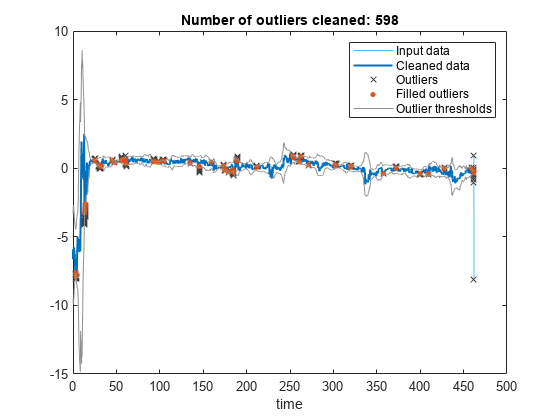

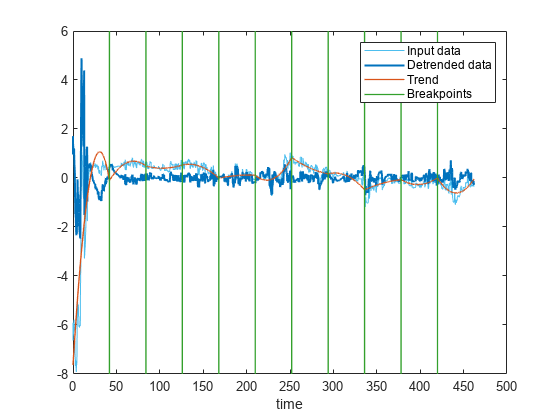

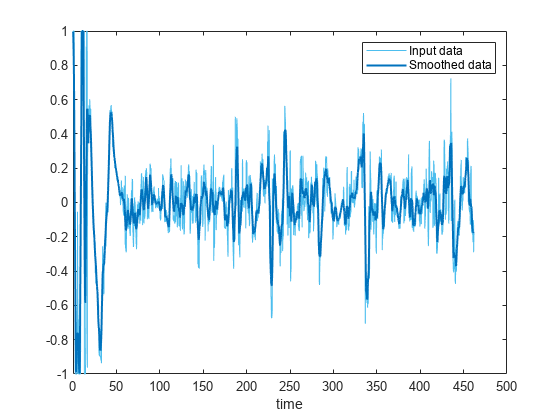

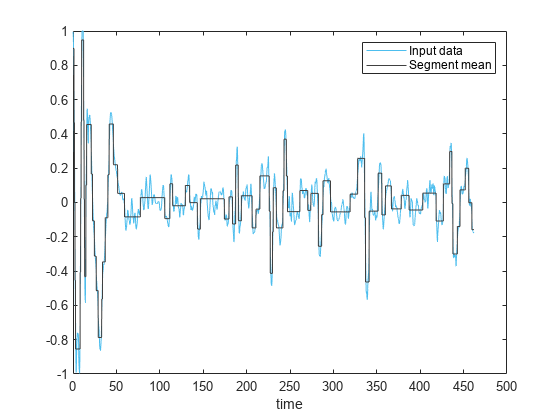

irisResult = struct with fields:
         meanFixation: 5.729583333333333
          varFixation: 32.940506153305208
    numFixationPerMin: 10.391109828258045


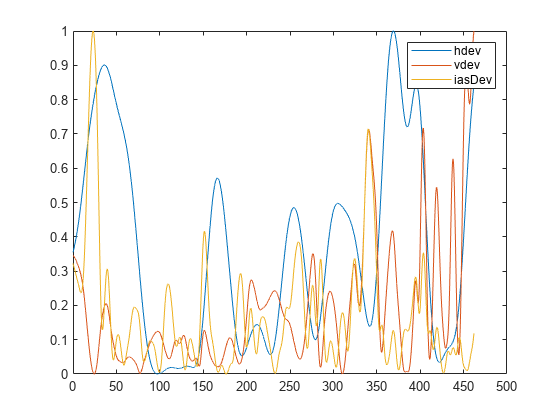

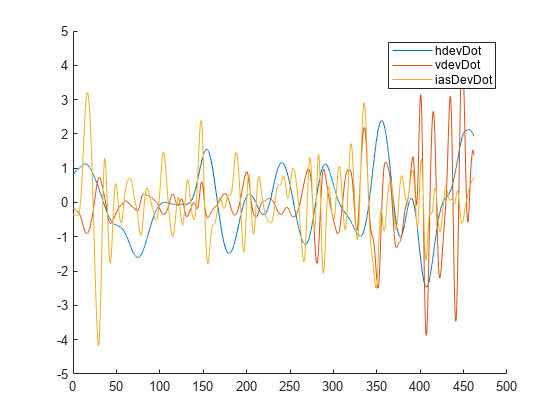

exceedanceResult = struct with fields:
    meanExceedance: 0.561006295125578


exceedanceResult = struct with fields:
    meanExceedance: 0.561006295125578
     varExceedance: 0.045409813966279


exceedanceResult = struct with fields:
            meanExceedance: 0.561006295125578
             varExceedance: 0.045409813966279
    detrendedVarExceedance: 0.036015933972654


Test Dir
logs\firstSeries\Alireza Ghaderi_07-11-2022_16-50-23
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 373
         endPVT: 386
     hoursAwake: 14
     selfRating: 3
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [22447×22 table]
    description: {''}
           time: "07-Nov-2022 16:50:23"
        caffein: 'None'

Before Test CAT
After Test CAT


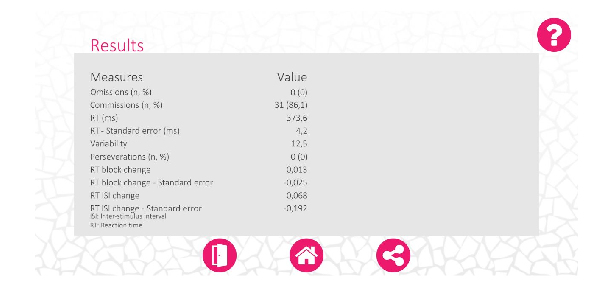

data = 1×22 table
    id      time      irisx    irisy    dxIris    dyIris     aileron      elevator     throttle      rudder        roll       pitch        hdev         vdev       dmeNM        ias       altitude      vvi       heading       rpm       latitude    longitude
    __    ________    _____    _____    ______    ______    __________    _________    _________    _________    ________    ________    ___

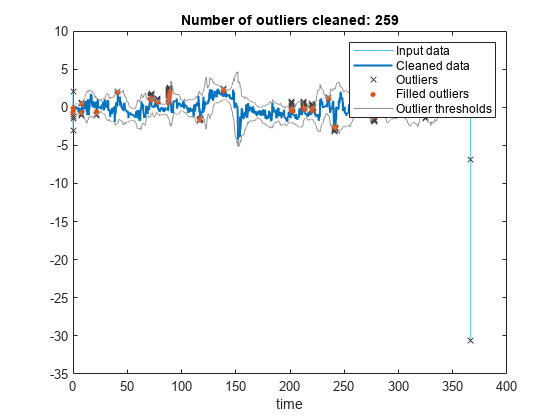

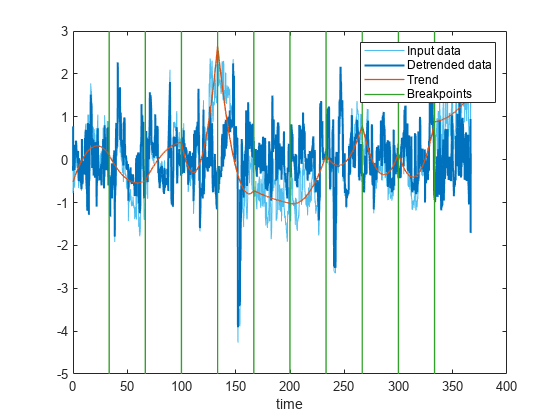

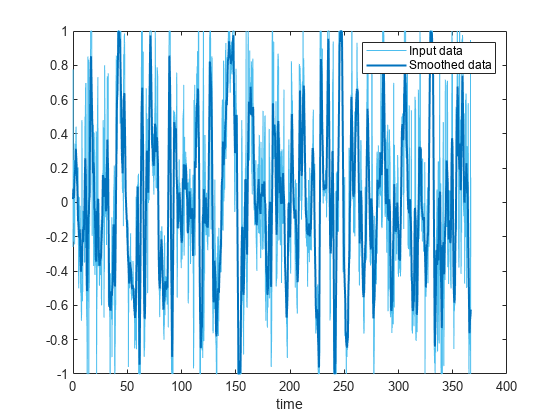

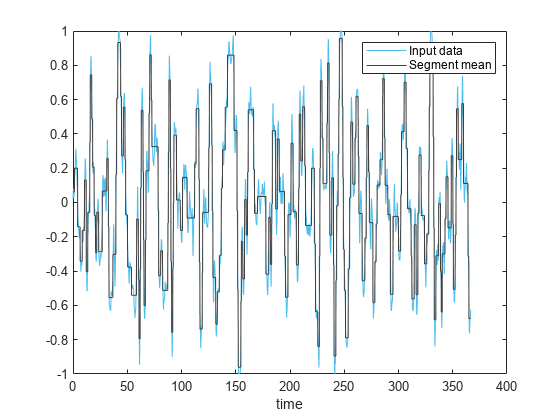

irisResult = struct with fields:
         meanFixation: 1.772682926829268
          varFixation: 1.683411339603593
    numFixationPerMin: 33.554605801582248


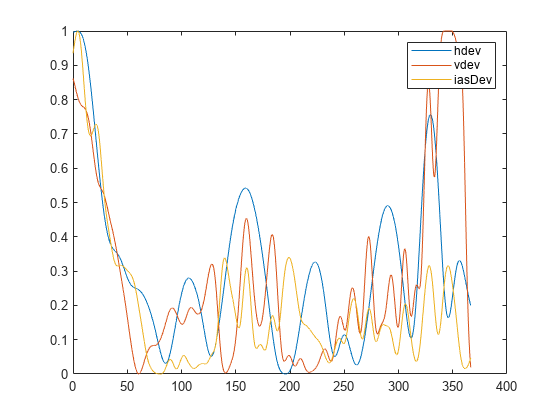

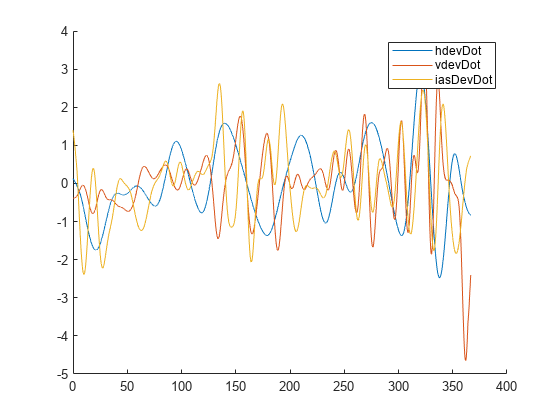

exceedanceResult = struct with fields:
    meanExceedance: 0.463226415900692


exceedanceResult = struct with fields:
    meanExceedance: 0.463226415900692
     varExceedance: 0.043699260524765


exceedanceResult = struct with fields:
            meanExceedance: 0.463226415900692
             varExceedance: 0.043699260524765
    detrendedVarExceedance: 0.046130053651765


Test Dir
logs\firstSeries\Alireza Ghaderi_08-01-2023_07-35-20
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 306
         endPVT: 381
     hoursAwake: 4
     selfRating: 6
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [33674×22 table]
    description: {''}
           time: "08-Jan-2023 07:35:20"
        caffein: 'None'

Before Test CAT
After Test CAT


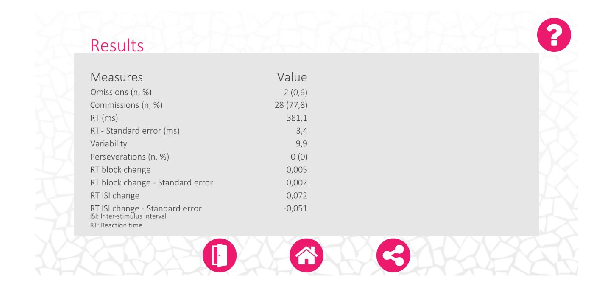

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron       elevator      throttle       rudder        roll       pitch        hdev         vdev       dmeNM        ias       altitude      vvi       heading      rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    __________    ___________    _________    __________    ________    ________

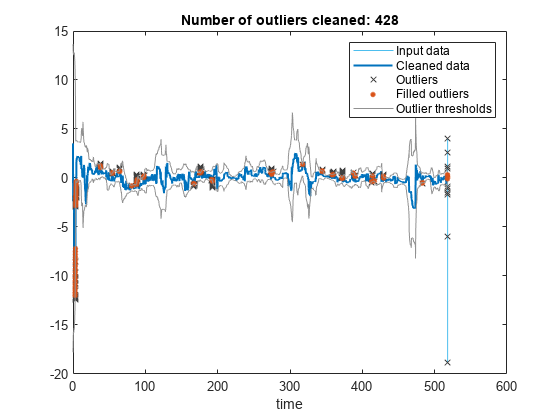

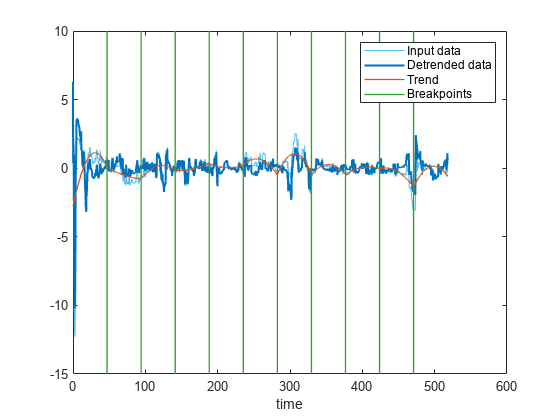

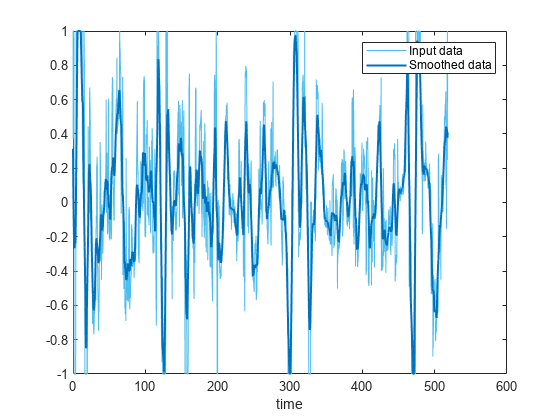

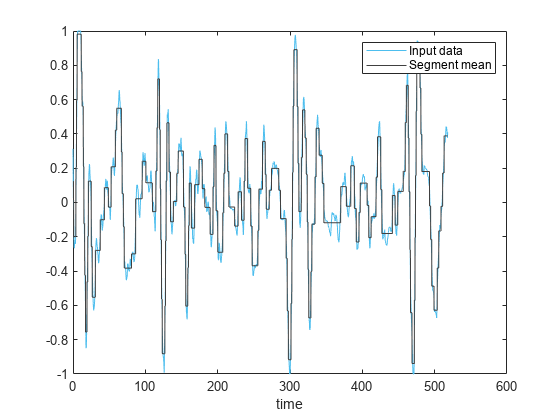

irisResult = struct with fields:
         meanFixation: 3.369956140350877
          varFixation: 8.826633699314502
    numFixationPerMin: 17.607310637750174


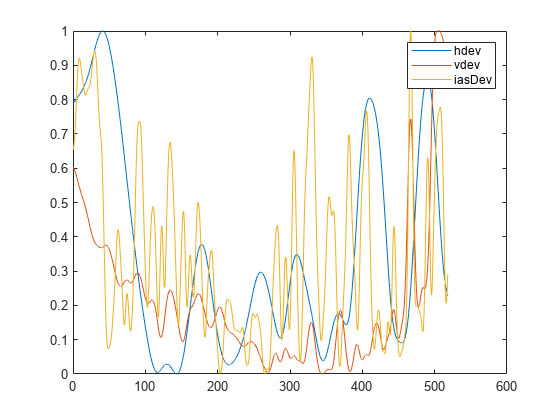

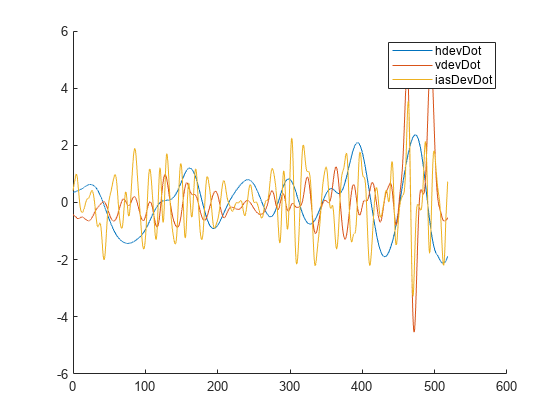

exceedanceResult = struct with fields:
    meanExceedance: 0.523932203163123


exceedanceResult = struct with fields:
    meanExceedance: 0.523932203163123
     varExceedance: 0.048182447224235


exceedanceResult = struct with fields:
            meanExceedance: 0.523932203163123
             varExceedance: 0.048182447224235
    detrendedVarExceedance: 0.047380144844024


Test Dir
logs\firstSeries\Alireza Ghaderi_10-02-2023_10-16-42
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 371
         endPVT: 380
     hoursAwake: 5
     selfRating: 6
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [32168×22 table]
    description: {'excite'}
           time: "10-Feb-2023 10:16:42"
        caffein: 'None'

Before Test CAT
After Test CAT


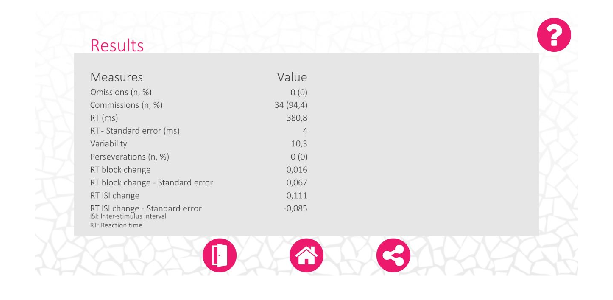

data = 1×22 table
    id         time          irisx    irisy    dxIris    dyIris      aileron       elevator      throttle       rudder         roll         pitch         hdev         vdev       dmeNM        ias       altitude       vvi       heading       rpm       latitude    longitude
    __    _______________    _____    _____    ______    ______    ___________    ___________    _________    ___________    _________    ___

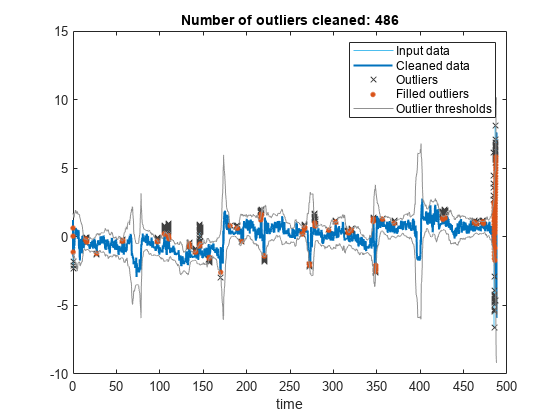

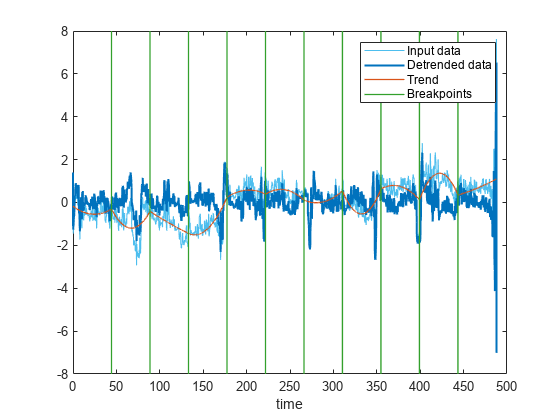

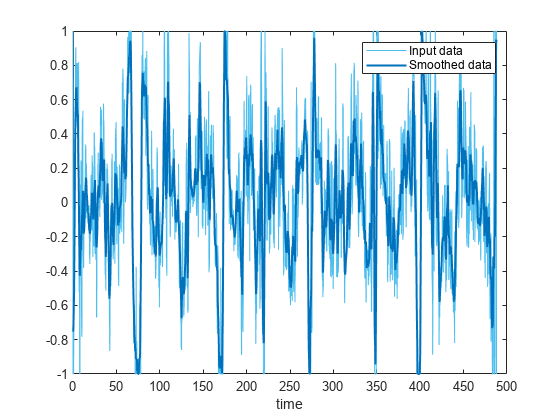

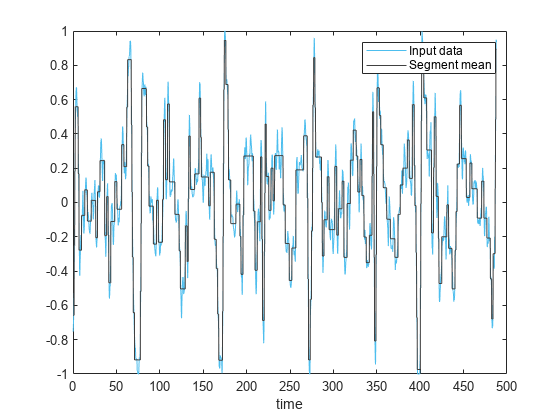

irisResult = struct with fields:
         meanFixation: 2.654826958105647
          varFixation: 3.662990919220428
    numFixationPerMin: 22.506149221098656


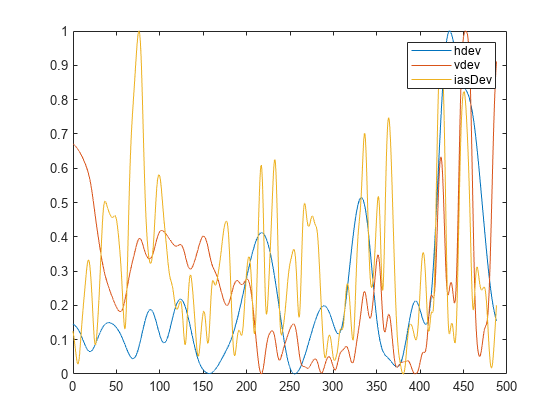

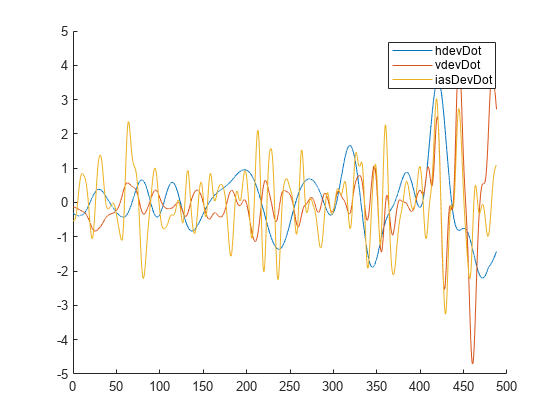

exceedanceResult = struct with fields:
    meanExceedance: 0.565904073735348


exceedanceResult = struct with fields:
    meanExceedance: 0.565904073735348
     varExceedance: 0.036558423552044


exceedanceResult = struct with fields:
            meanExceedance: 0.565904073735348
             varExceedance: 0.036558423552044
    detrendedVarExceedance: 0.036513625830284


Test Dir
logs\firstSeries\Alireza Ghaderi_12-02-2023_04-20-58
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 383
         endPVT: 393
     hoursAwake: 2
     selfRating: 8
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [28037×22 table]
    description: {''}
           time: "12-Feb-2023 04:20:57"
        caffein: 'None'

Before Test CAT
After Test CAT


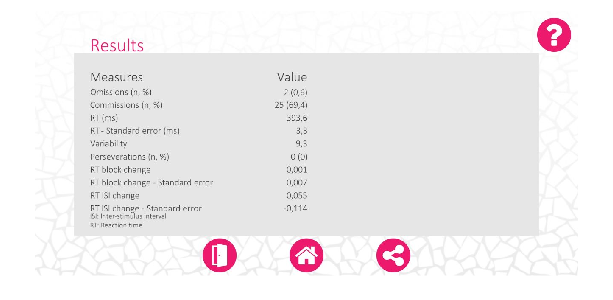

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron        elevator      throttle       rudder         roll        pitch        hdev          vdev        dmeNM        ias       altitude       vvi       heading       rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    __________    ____________    _________    ___________    ________    __

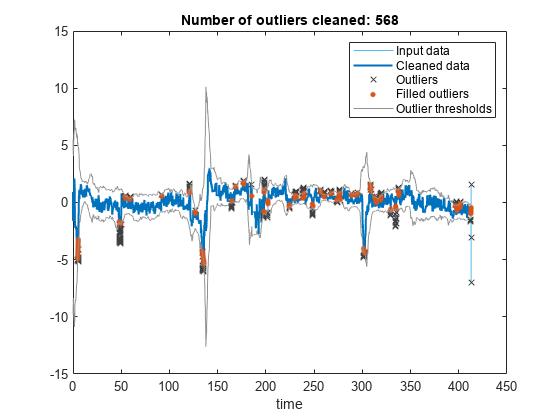

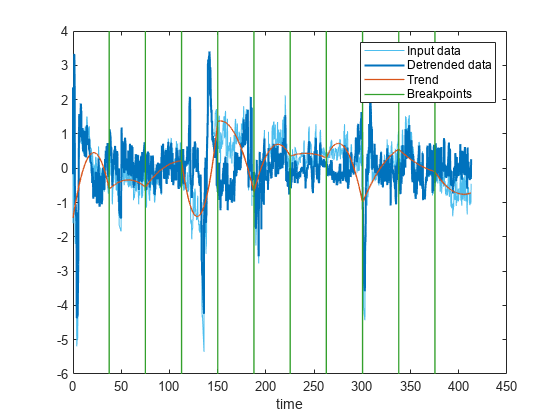

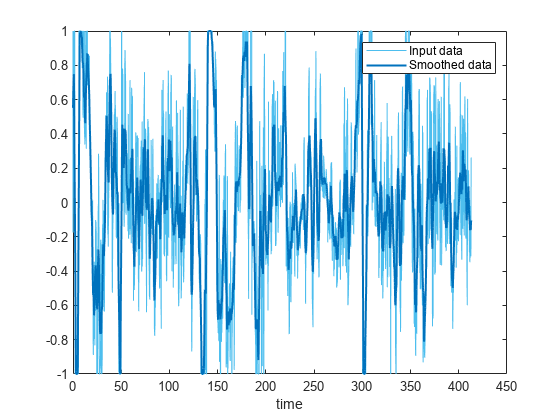

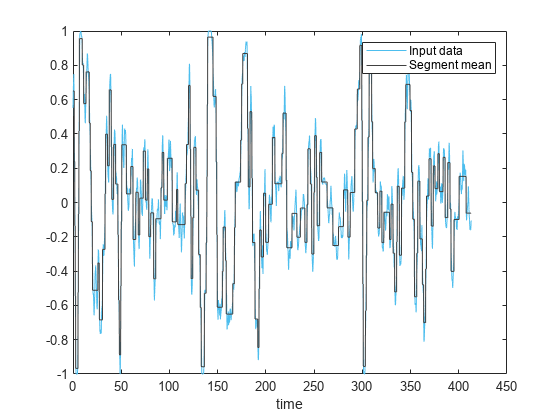

irisResult = struct with fields:
         meanFixation: 2.321714285714286
          varFixation: 2.565975332968437
    numFixationPerMin: 25.436046511627907


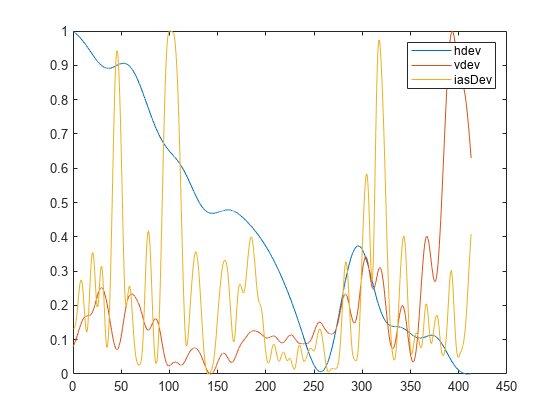

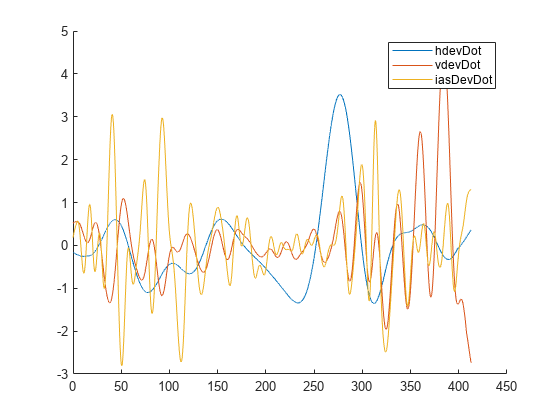

exceedanceResult = struct with fields:
    meanExceedance: 0.518997662579111


exceedanceResult = struct with fields:
    meanExceedance: 0.518997662579111
     varExceedance: 0.063063286606329


exceedanceResult = struct with fields:
            meanExceedance: 0.518997662579111
             varExceedance: 0.063063286606329
    detrendedVarExceedance: 0.049873878184465


Test Dir
logs\firstSeries\Alireza Ghaderi_12-02-2023_11-07-17
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 383
         endPVT: 389
     hoursAwake: 7
     selfRating: 5
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [24913×22 table]
    description: {'xp 12'}
           time: "12-Feb-2023 11:07:17"
        caffein: 'None'

Before Test CAT
After Test CAT


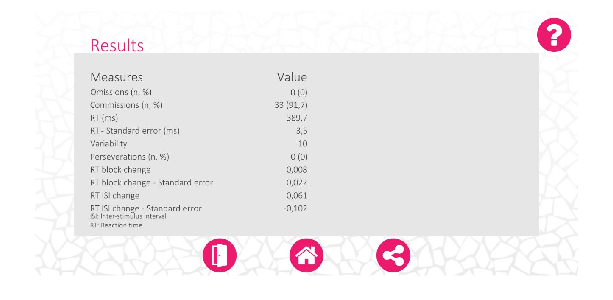

data = 1×22 table
    id         time          irisx    irisy    dxIris    dyIris      aileron       elevator     throttle        rudder         roll        pitch        hdev          vdev        dmeNM        ias      altitude      vvi       heading       rpm       latitude    longitude
    __    _______________    _____    _____    ______    ______    ___________    __________    _________    ____________    _________    _____

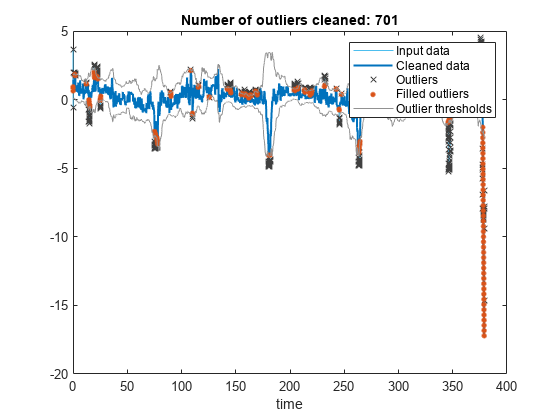

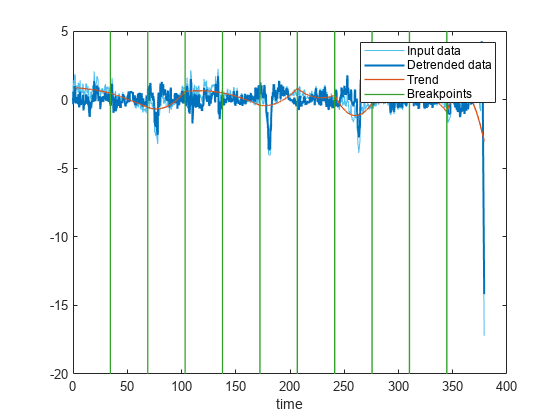

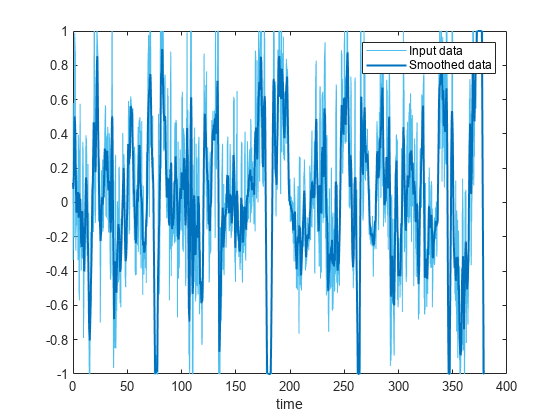

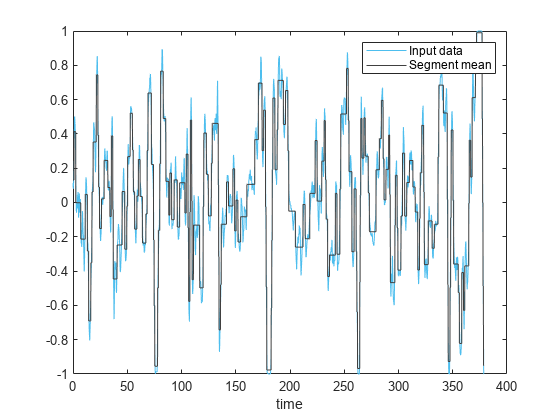

irisResult = struct with fields:
         meanFixation: 2.039819819819820
          varFixation: 2.169885233059147
    numFixationPerMin: 29.290175037382358


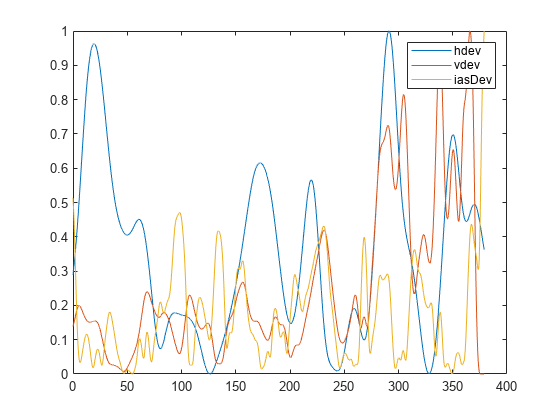

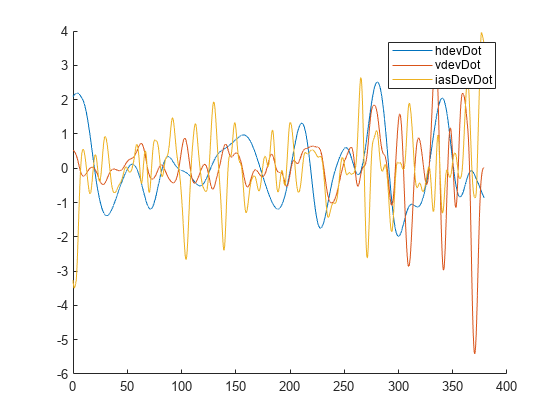

exceedanceResult = struct with fields:
    meanExceedance: 0.540122314124613


exceedanceResult = struct with fields:
    meanExceedance: 0.540122314124613
     varExceedance: 0.052548729124043


exceedanceResult = struct with fields:
            meanExceedance: 0.540122314124613
             varExceedance: 0.052548729124043
    detrendedVarExceedance: 0.053469357564618


Test Dir
logs\firstSeries\Alireza Ghaderi_13-02-2023_04-48-50
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 398
         endPVT: 381
     hoursAwake: 2
     selfRating: 8
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [30946×22 table]
    description: {''}
           time: "13-Feb-2023 04:48:50"
        caffein: 'None'

Before Test CAT
After Test CAT


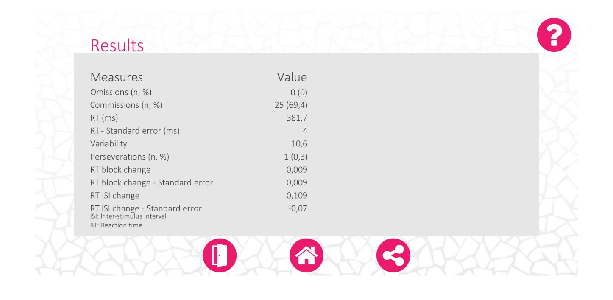

data = 1×22 table
    id         time          irisx    irisy    dxIris    dyIris     aileron       elevator     throttle        rudder         roll        pitch        hdev        vdev        dmeNM       ias       altitude       vvi       heading       rpm      latitude    longitude
    __    _______________    _____    _____    ______    ______    __________    __________    _________    ____________    ________    _________<

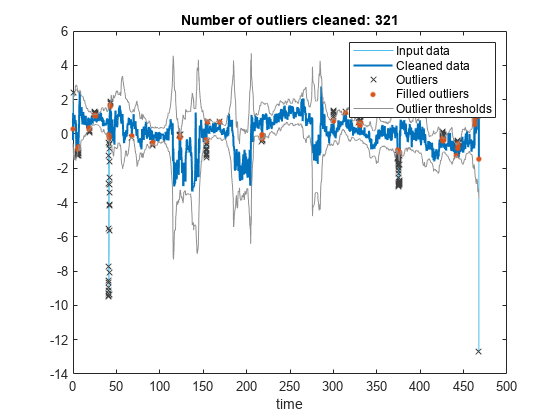

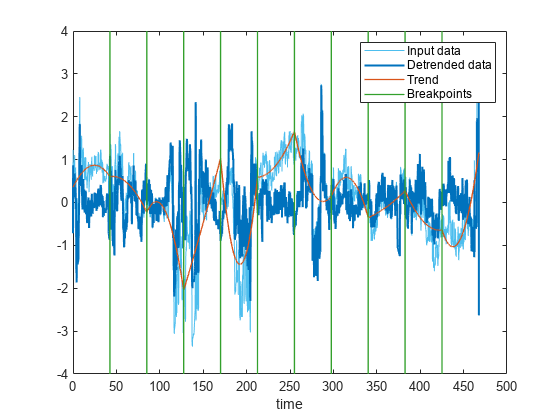

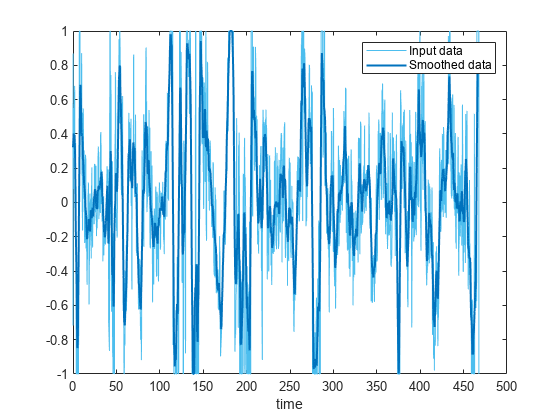

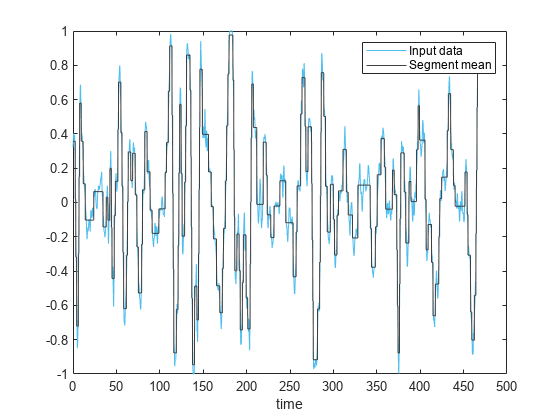

irisResult = struct with fields:
         meanFixation: 2.603745318352060
          varFixation: 4.777349358499613
    numFixationPerMin: 22.838406158671326


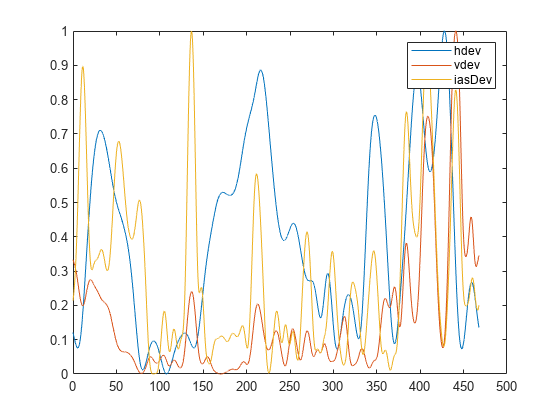

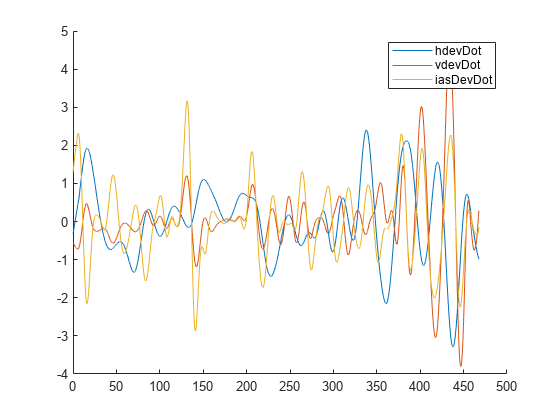

exceedanceResult = struct with fields:
    meanExceedance: 0.527195069177302


exceedanceResult = struct with fields:
    meanExceedance: 0.527195069177302
     varExceedance: 0.046236852243977


exceedanceResult = struct with fields:
            meanExceedance: 0.527195069177302
             varExceedance: 0.046236852243977
    detrendedVarExceedance: 0.048008864188967


Test Dir
logs\firstSeries\Alireza Ghaderi_14-02-2023_04-18-01
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 405
         endPVT: 397
     hoursAwake: 1
     selfRating: 9
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [33257×22 table]
    description: {''}
           time: "14-Feb-2023 04:18:01"
        caffein: 'None'

Before Test CAT
After Test CAT


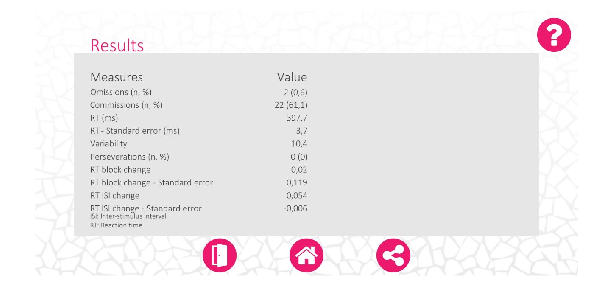

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris      aileron       elevator     throttle       rudder         roll       pitch        hdev         vdev        dmeNM        ias      altitude       vvi       heading       rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    ___________    __________    _________    ___________    ________    _______

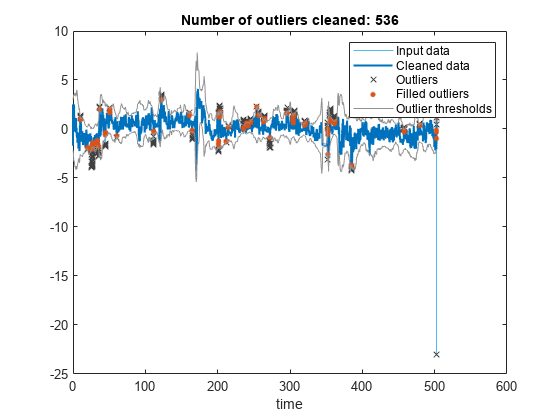

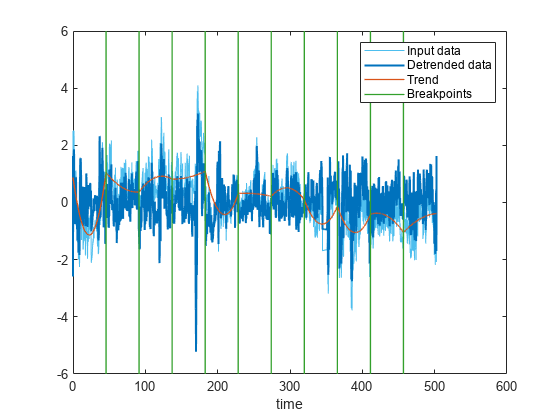

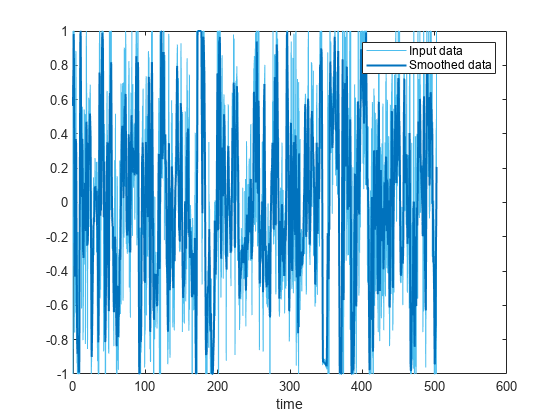

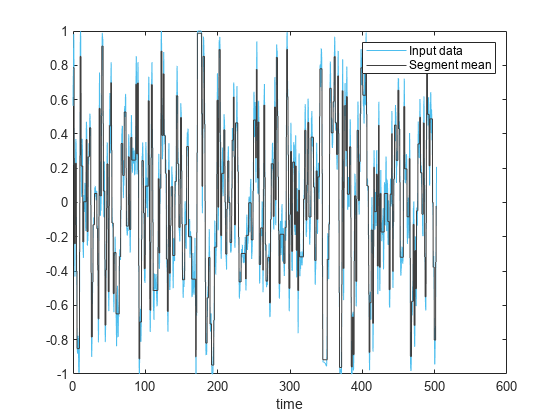

irisResult = struct with fields:
         meanFixation: 1.511782477341390
          varFixation: 1.241271526951284
    numFixationPerMin: 39.519766516317326


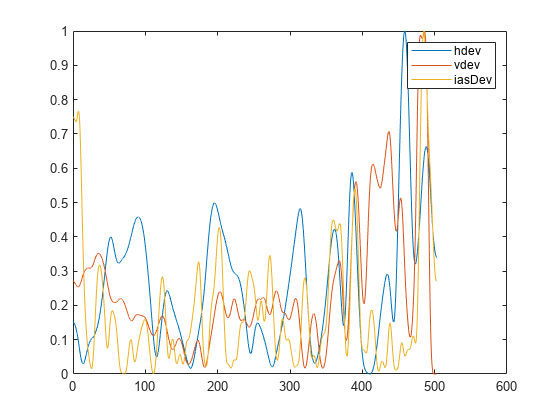

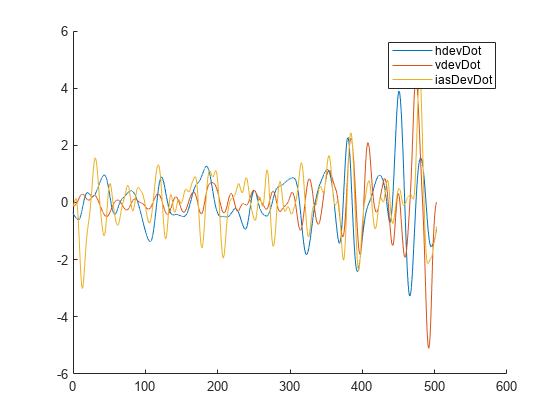

exceedanceResult = struct with fields:
    meanExceedance: 0.531821214839162


exceedanceResult = struct with fields:
    meanExceedance: 0.531821214839162
     varExceedance: 0.047653957386839


exceedanceResult = struct with fields:
            meanExceedance: 0.531821214839162
             varExceedance: 0.047653957386839
    detrendedVarExceedance: 0.038102763532643


Test Dir
logs\firstSeries\Alireza Ghaderi_17-01-2023_07-19-41
Pilot Info
           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 378
         endPVT: 380
     hoursAwake: 5
     selfRating: 5
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [31816×22 table]
    description: {'Hungry'}
           time: "17-Jan-2023 07:19:41"
        caffein: 'None'

Before Test CAT
After Test CAT


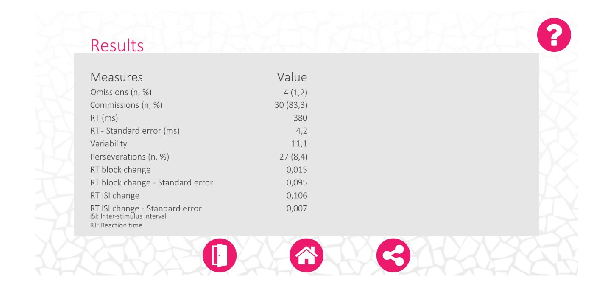

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron      elevator     throttle       rudder         roll        pitch          hdev         vdev       dmeNM        ias       altitude       vvi       heading       rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    _________    __________    _________    ___________    ________    ________

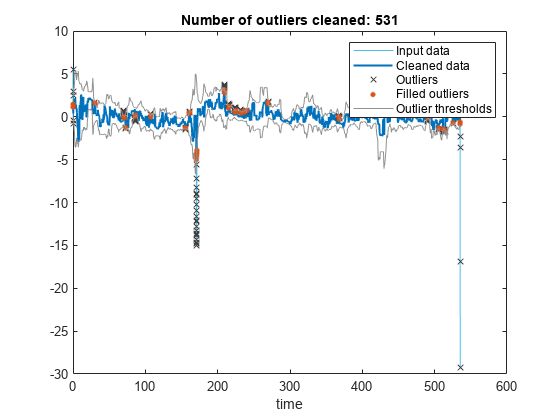

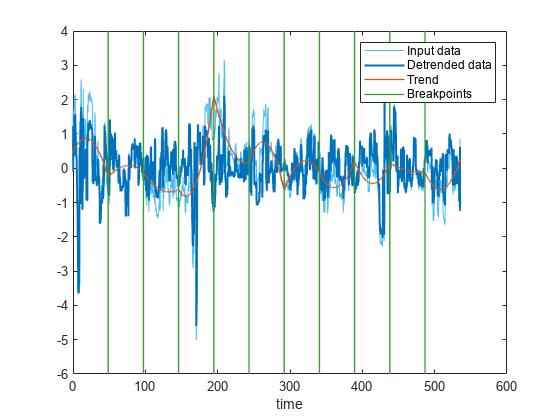

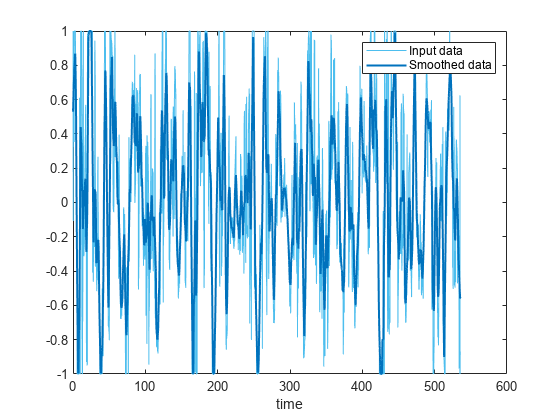

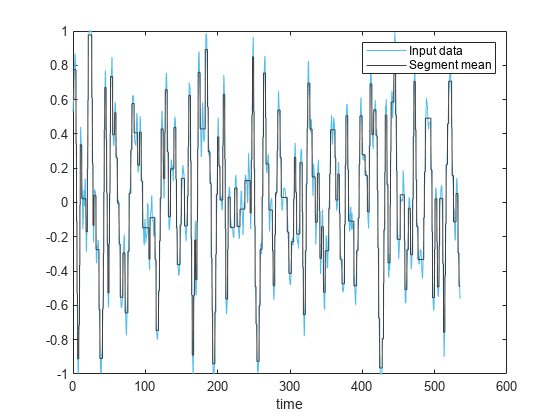

irisResult = struct with fields:
         meanFixation: 2.191769547325103
          varFixation: 2.605606910859435
    numFixationPerMin: 27.237063328974411


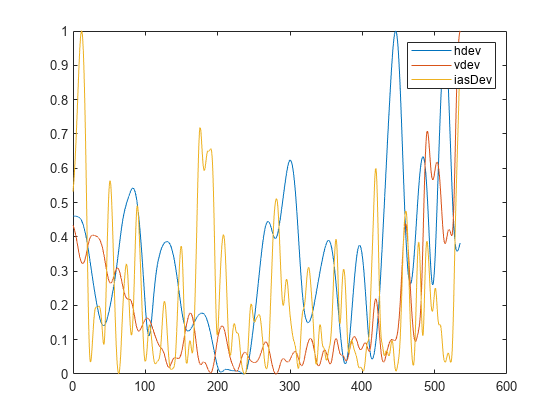

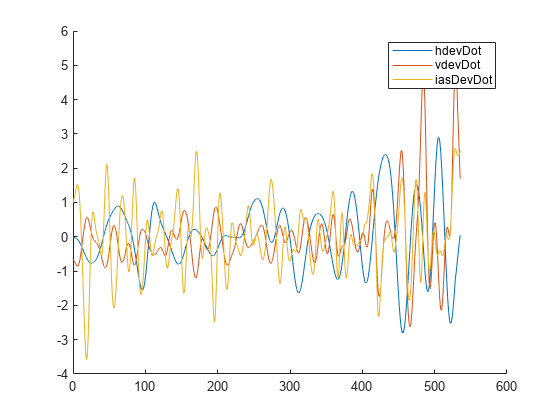

exceedanceResult = struct with fields:
    meanExceedance: 0.589774645364862


exceedanceResult = struct with fields:
    meanExceedance: 0.589774645364862
     varExceedance: 0.036827030025503


exceedanceResult = struct with fields:
            meanExceedance: 0.589774645364862
             varExceedance: 0.036827030025503
    detrendedVarExceedance: 0.030826562821458


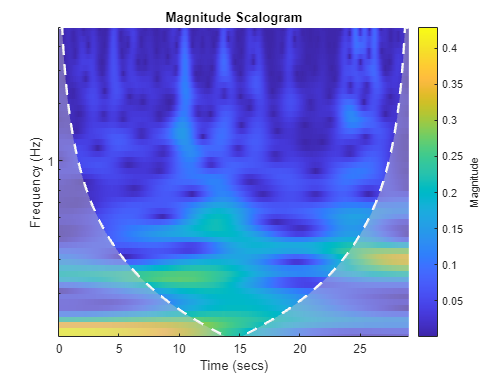



% Loop through the directory names and open autoExperimentAnalyzer.mlx
for bi = 1:length(dirNames)
    dirTest = dirNames{bi};
    dirPath = dirPaths{bi};
    scriptPath = fullfile(cwd, 'autoExperimentAnalyzer.mlx');
    %open(scriptPath);
    run(scriptPath);
    trialData(bi) = output;
end

%final data for all tests is gathered in trialData.




saveTrialData = true

saveTrialData = logical
   1


if (saveTrialData==1)
save TrialData.mat trialData;
end
